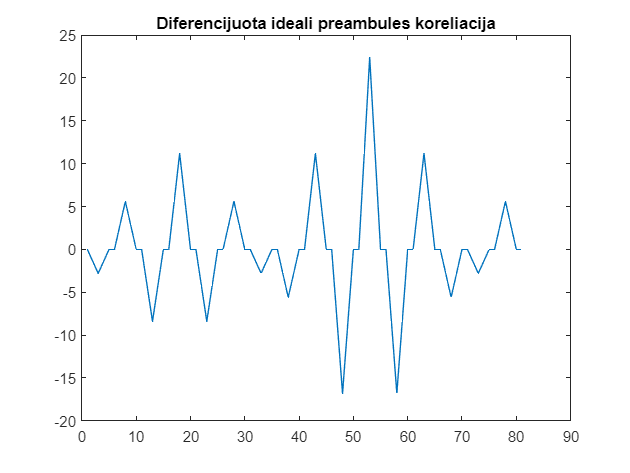

load Apkirpta_ideali_preambule_d.mat %yy-ideali diferencijuota preambule
y53 = yy(1:53);
y81 = yy(1:81);
fdiskret = 10E6;
tdiskret = 1/fdiskret;

tprescaler = 10;

idealOne = [ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler))];
idealZero = [zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

dataSend = "101101110101010101011000111";
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1);

pastumimasN = 2;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;

pastumtas = [zeros(1, pastumimasN), ADCsignal(1:length(ADCsignal)-pastumimasN)];
diferencijuotasPilnas = ADCsignal - pastumtas;

idealusDiskretizuotas = idealSignal(1:10:length(idealSignal));
pastumtasi = [zeros(1, pastumimasN), idealusDiskretizuotas(1:length(idealusDiskretizuotas)-pastumimasN)];
difIdealus = idealusDiskretizuotas - pastumtasi;

diferencijuotaPreambule = diferencijuotaPreambule(6:57);
koreliacijaPreambules1 = GenerateConv(diferencijuotasPilnas, diferencijuotaPreambule); %diferencijuotas
koreliacijaPreambules2 = GenerateConv(koreliacijaPreambules1, y53); %diferencijuotas
koreliacijaPreambules3 = GenerateConv(koreliacijaPreambules1, y81); %diferencijuotas

plot(yy)
title("Diferencijuota ideali preambules koreliacija")

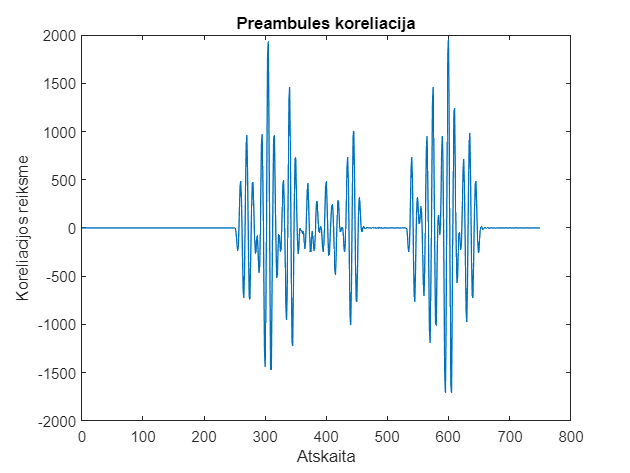


plot(koreliacijaPreambules1)
title("Preambules koreliacija")
xlabel("Atskaita")
ylabel("Koreliacijos reiksme")

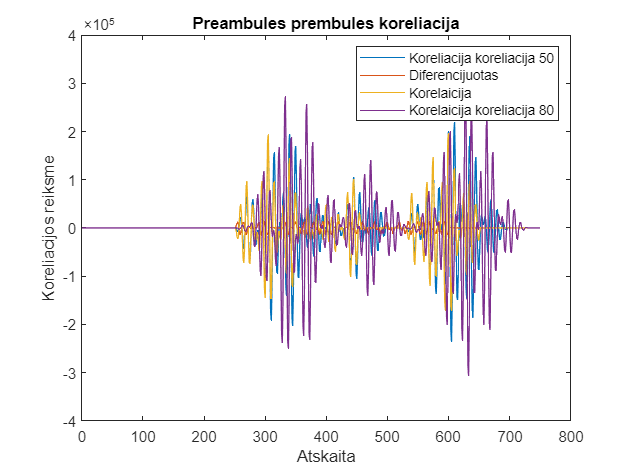


plot(koreliacijaPreambules2)
hold on

plot(diferencijuotasPilnas*100)
plot(koreliacijaPreambules1*100)
plot(koreliacijaPreambules3*1)
hold off
legend("Koreliacija koreliacija 50", "Diferencijuotas", "Korelaicija", "Korelaicija koreliacija 80")
title("Preambules prembules koreliacija")
xlabel("Atskaita")
ylabel("Koreliacijos reiksme")

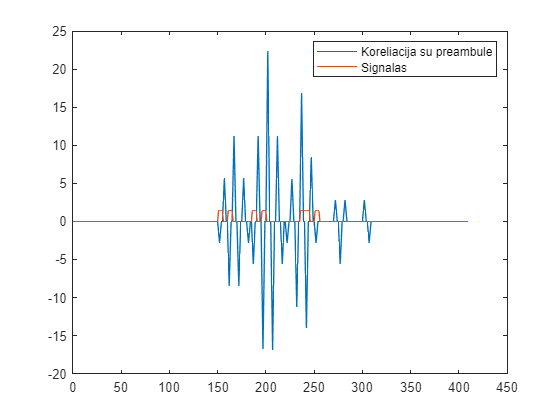

%Išsaugom idealia preambule (reiks pasiekist i betriuksme)
clear
fdiskret = 10E6;
tdiskret = 1/fdiskret;

tprescaler = 10;

idealOne = [ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler))];
idealZero = [zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

dataSend = "101";
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1.4);

pastumimasN = 2;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;

pastumtas = [zeros(1, pastumimasN), ADCsignal(1:length(ADCsignal)-pastumimasN)];
diferencijuotasPilnas = ADCsignal - pastumtas;

idealusDiskretizuotas = idealSignal(1:10:length(idealSignal));
pastumtasi = [zeros(1, pastumimasN), idealusDiskretizuotas(1:length(idealusDiskretizuotas)-pastumimasN)];
difIdealus = idealusDiskretizuotas - pastumtasi;

diferencijuotaPreambule = diferencijuotaPreambule(6:57);
y = GenerateConv(difIdealus, diferencijuotaPreambule); %diferencijuotas

dataSend = "011";
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1.4);

pastumtas = [zeros(1, pastumimasN), ADCsignal(1:length(ADCsignal)-pastumimasN)];
diferencijuotasPilnas = ADCsignal - pastumtas;

idealusDiskretizuotas = idealSignal(1:10:length(idealSignal));
pastumtasi = [zeros(1, pastumimasN), idealusDiskretizuotas(1:length(idealusDiskretizuotas)-pastumimasN)];
difIdealus = idealusDiskretizuotas - pastumtasi;

y2 = GenerateConv(difIdealus, diferencijuotaPreambule); %diferencijuotas
yy = y(150:230);

plot(y)
hold on

plot(idealSignal(1:10:length(idealSignal)))
hold off
legend("Koreliacija su preambule", "Signalas")

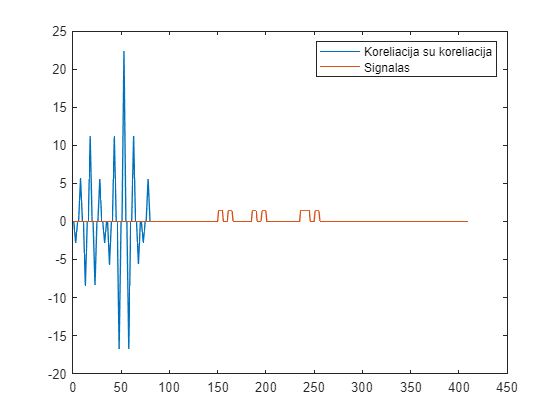

plot(yy)
hold on
plot(idealSignal(1:10:length(idealSignal)))
hold off
legend("Koreliacija su koreliacija", "Signalas")

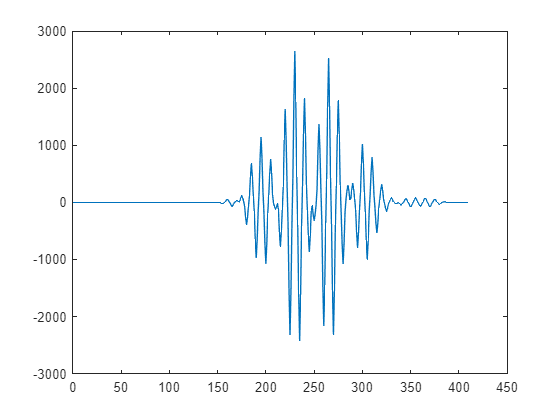


korkor = GenerateConv(y, yy); %diferencijuotas
plot(korkor)

%Is 2 kartu padaro i 2.3 15% geriau TEORISKAI
save("Pilna_ideali_preambule_d.mat", "y");
save("Apkirpta_ideali_preambule_d.mat", "yy");